# ACTIVITY 6: MORPHOLOGICAL OPERATIONS

## ACTIVITY 6.1

## Structuring Elements

SE1 = strel([0 0 0; 0 1 1; 0 1 1]);
SE2 = strel([0 0 0; 0 1 1; 0 0 0]);
SE3 = strel("square", 5);
SE1corr = strel([1 1 0; 1 1 0; 0 0 0]);
SE2corr = strel([0 0 0; 1 1 0; 0 0 0]);


## Images of SE

se1img = zeros(20);
se1img(10:11, 10:11) = 1;
se1img(10, 10) = 0.5;

se2img = zeros(20);
se2img(10, 10:11) = 1;
se2img(10, 10) = 0.5;

se3img = zeros(20);
se3img(8:12, 8:12) = 1;
se3img(10, 10) = 0.5;


## Correction of SE

se1imgcorr = zeros(20);
se1imgcorr(10:11, 10:11) = 1;
se1imgcorr(11, 11) = 0.5;

se2imgcorr = zeros(20);
se2imgcorr(10, 10:11) = 1;
se2imgcorr(10, 11) = 0.5;


## Images

% 5x5 square
bg1 = zeros(20);
bg1(8:12, 8:12) = 1;
% hollow 10x10 square, 2 boxes thick
bg2 = zeros(20);
bg2(6:15, 6:15) = 1;
bg2(8:13, 8:13) = 0;
% plus sign, one box thick, 5 boxes along each line
bg3 = zeros(20);
bg3(8:12, 10) = 1;
bg3(10, 8:12) = 1;
% dumbbell
bg4 = zeros(20);
bg4(8:12, 5:9) = 1;
bg4(10, 10:12) = 1;
bg4(8:12, 13:17) = 1;

## Plotting of Dilation

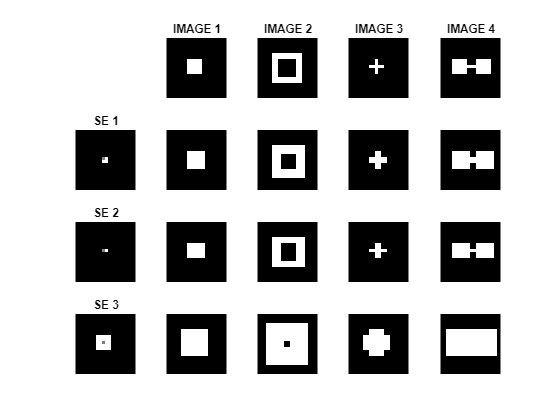

figure;
% Images
subplot(4, 5, 2); imshow(bg1); axis off; axis square; title('IMAGE 1');
subplot(4, 5, 3); imshow(bg2);axis off; axis square; title('IMAGE 2'); subplot(4, 5, 4); imshow(bg3);axis off; axis square; title('IMAGE 3'); subplot(4, 5, 5); imshow(bg4); axis off; axis square; title('IMAGE 4');

% Structural elements
subplot(4, 5, 6); imshow(imresize(se1img, 10, "nearest")); title('SE 1');
subplot(4, 5, 11); imshow(imresize(se2img, 10, "nearest")); title('SE 2');
subplot(4, 5, 16); imshow(imresize(se3img, 10, "nearest")); title('SE 3');

% Dilation operations
% Row 2
subplot(4, 5, 7); imagesc(imdilate(bg1, SE1)); axis off; axis square;
subplot(4, 5, 8); imagesc(imdilate(bg2, SE1)); axis off; axis square;
subplot(4, 5, 9); imagesc(imdilate(bg3, SE1)); axis off; axis square;
subplot(4, 5, 10); imagesc(imdilate(bg4, SE1)); axis off; axis square;
% Row 3
subplot(4, 5, 12); imagesc(imdilate(bg1, SE2)); axis off; axis square;
subplot(4, 5, 13); imagesc(imdilate(bg2, SE2)); axis off; axis square;
subplot(4, 5, 14); imagesc(imdilate(bg3, SE2)); axis off; axis square;
subplot(4, 5, 15); imagesc(imdilate(bg4, SE2)); axis off; axis square;
% Row 4
subplot(4, 5, 17); imagesc(imdilate(bg1, SE3)); axis off; axis square;
subplot(4, 5, 18); imagesc(imdilate(bg2, SE3)); axis off; axis square;
subplot(4, 5, 19); imagesc(imdilate(bg3, SE3)); axis off; axis square;
subplot(4, 5, 20); imagesc(imdilate(bg4, SE3)); axis off; axis square;
colormap gray;

## Plotting of Dilation using corrected SE

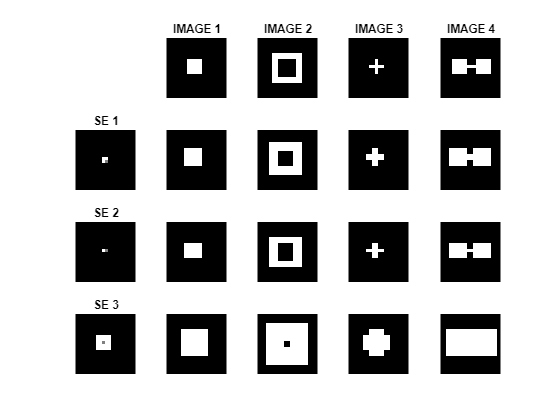

figure;
% Images
subplot(4, 5, 2); imshow(bg1); axis off; axis square; title('IMAGE 1');
subplot(4, 5, 3); imshow(bg2);axis off; axis square; title('IMAGE 2');
subplot(4, 5, 4); imshow(bg3);axis off; axis square; title('IMAGE 3');
subplot(4, 5, 5); imshow(bg4); axis off; axis square; title('IMAGE 4');

% Structural elements
subplot(4, 5, 6); imshow(imresize(se1imgcorr, 10, "nearest")); title('SE 1');
subplot(4, 5, 11); imshow(imresize(se2imgcorr, 10, "nearest")); title('SE 2');
subplot(4, 5, 16); imshow(imresize(se3img, 10, "nearest")); title('SE 3');

% Dilation operations
% Row 2
subplot(4, 5, 7); imagesc(imdilate(bg1, SE1corr)); axis off; axis square;
subplot(4, 5, 8); imagesc(imdilate(bg2, SE1corr)); axis off; axis square;
subplot(4, 5, 9); imagesc(imdilate(bg3, SE1corr)); axis off; axis square;
subplot(4, 5, 10); imagesc(imdilate(bg4, SE1corr)); axis off; axis square;
% Row 3
subplot(4, 5, 12); imagesc(imdilate(bg1, SE2corr)); axis off; axis square;
subplot(4, 5, 13); imagesc(imdilate(bg2, SE2corr)); axis off; axis square;
subplot(4, 5, 14); imagesc(imdilate(bg3, SE2corr)); axis off; axis square;
subplot(4, 5, 15); imagesc(imdilate(bg4, SE2corr)); axis off; axis square;
% Row 4
subplot(4, 5, 17); imagesc(imdilate(bg1, SE3)); axis off; axis square;
subplot(4, 5, 18); imagesc(imdilate(bg2, SE3)); axis off; axis square;
subplot(4, 5, 19); imagesc(imdilate(bg3, SE3)); axis off; axis square;
subplot(4, 5, 20); imagesc(imdilate(bg4, SE3)); axis off; axis square;
colormap gray;

## Plotting of Erosion

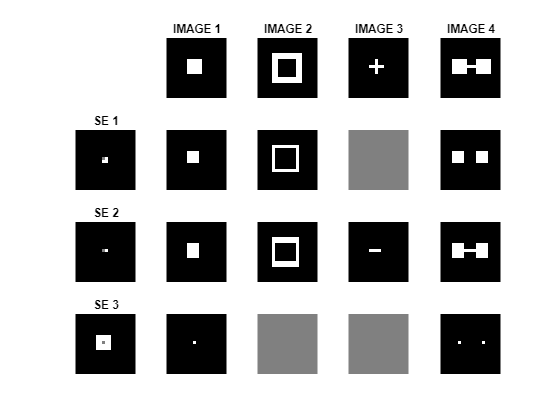

figure;
% Images
% Images
subplot(4, 5, 2); imshow(bg1); axis off; axis square; title('IMAGE 1');
subplot(4, 5, 3); imshow(bg2);axis off; axis square; title('IMAGE 2');
subplot(4, 5, 4); imshow(bg3);axis off; axis square; title('IMAGE 3');
subplot(4, 5, 5); imshow(bg4); axis off; axis square; title('IMAGE 4');

% Structural elements
subplot(4, 5, 6); imshow(imresize(se1img, 10, "nearest")); title('SE 1');
subplot(4, 5, 11); imshow(imresize(se2img, 10, "nearest")); title('SE 2');
subplot(4, 5, 16); imshow(imresize(se3img, 10, "nearest")); title('SE 3');

% Erosion operations
% Row 2
subplot(4, 5, 7); imagesc(imerode(bg1, SE1)); axis off; axis square;
subplot(4, 5, 8); imagesc(imerode(bg2, SE1)); axis off; axis square;
subplot(4, 5, 9); imagesc(imerode(bg3, SE1)); axis off; axis square;
subplot(4, 5, 10); imagesc(imerode(bg4, SE1)); axis off; axis square;
% Row 3
subplot(4, 5, 12); imagesc(imerode(bg1, SE2)); axis off; axis square;
subplot(4, 5, 13); imagesc(imerode(bg2, SE2)); axis off; axis square;
subplot(4, 5, 14); imagesc(imerode(bg3, SE2)); axis off; axis square;
subplot(4, 5, 15); imagesc(imerode(bg4, SE2)); axis off; axis square;
% Row 4
subplot(4, 5, 17); imagesc(imerode(bg1, SE3)); axis off; axis square;
subplot(4, 5, 18); imagesc(imerode(bg2, SE3)); axis off; axis square;
subplot(4, 5, 19); imagesc(imerode(bg3, SE3)); axis off; axis square;
subplot(4, 5, 20); imagesc(imerode(bg4, SE3)); axis off; axis square;
colormap gray;

## Plotting of Erosion using corrected SE

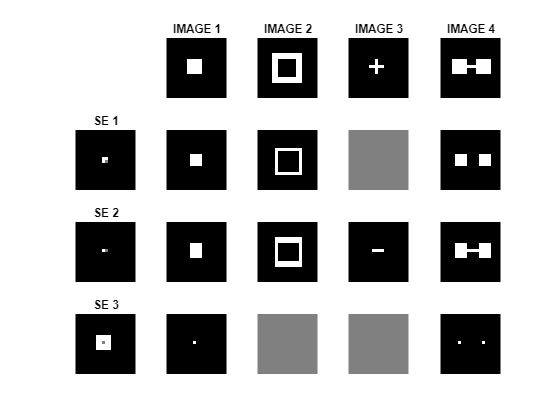

figure;
% Images
subplot(4, 5, 2); imshow(bg1); axis off; axis square; title('IMAGE 1');
subplot(4, 5, 3); imshow(bg2);axis off; axis square; title('IMAGE 2');
subplot(4, 5, 4); imshow(bg3);axis off; axis square; title('IMAGE 3');
subplot(4, 5, 5); imshow(bg4); axis off; axis square; title('IMAGE 4');

% Structural elements
subplot(4, 5, 6); imshow(imresize(se1imgcorr, 10, "nearest")); title('SE 1');
subplot(4, 5, 11); imshow(imresize(se2imgcorr, 10, "nearest")); title('SE 2');
subplot(4, 5, 16); imshow(imresize(se3img, 10, "nearest")); title('SE 3');

% Erosion operations
% Row 2
subplot(4, 5, 7); imagesc(imerode(bg1, SE1corr)); axis off; axis square;
subplot(4, 5, 8); imagesc(imerode(bg2, SE1corr)); axis off; axis square;
subplot(4, 5, 9); imagesc(imerode(bg3, SE1corr)); axis off; axis square;
subplot(4, 5, 10); imagesc(imerode(bg4, SE1corr)); axis off; axis square;
% Row 3
subplot(4, 5, 12); imagesc(imerode(bg1, SE2corr)); axis off; axis square;
subplot(4, 5, 13); imagesc(imerode(bg2, SE2corr)); axis off; axis square;
subplot(4, 5, 14); imagesc(imerode(bg3, SE2corr)); axis off; axis square;
subplot(4, 5, 15); imagesc(imerode(bg4, SE2corr)); axis off; axis square;
% Row 4
subplot(4, 5, 17); imagesc(imerode(bg1, SE3)); axis off; axis square;
subplot(4, 5, 18); imagesc(imerode(bg2, SE3)); axis off; axis square;
subplot(4, 5, 19); imagesc(imerode(bg3, SE3)); axis off; axis square;
subplot(4, 5, 20); imagesc(imerode(bg4, SE3)); axis off; axis square;
colormap gray;

## Activity 6.2

## Original and grayscale image

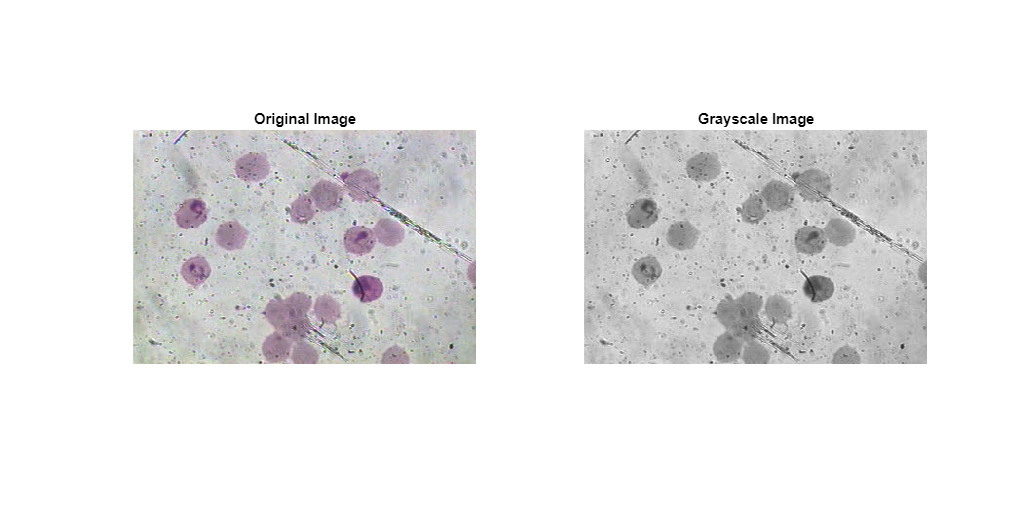

I = imread("malaria(1).jpeg");
Igray = rgb2gray(I);
figure('Position', [200, 200, 1024, 512]);
subplot(1,2,1); imshow(I); title("Original Image");
subplot(1,2,2); imshow(Igray); title('Grayscale Image');

## Histogram

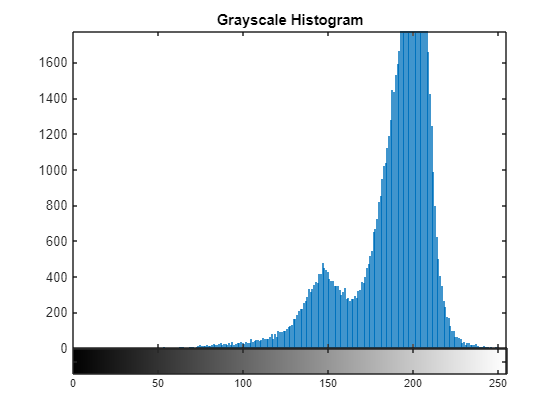

figure; imhist (Igray); title("Grayscale Histogram");

## Thresholded image

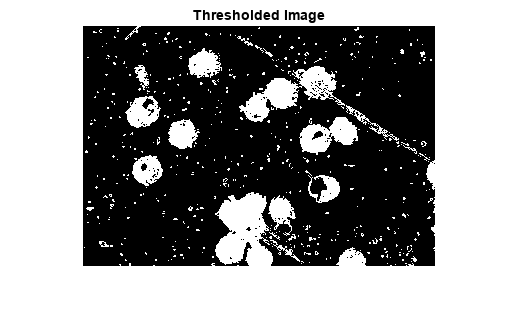

BW = and(Igray < 164, Igray > 100);
figure; imshow(BW); title('Thresholded Image');

## Morphed Image

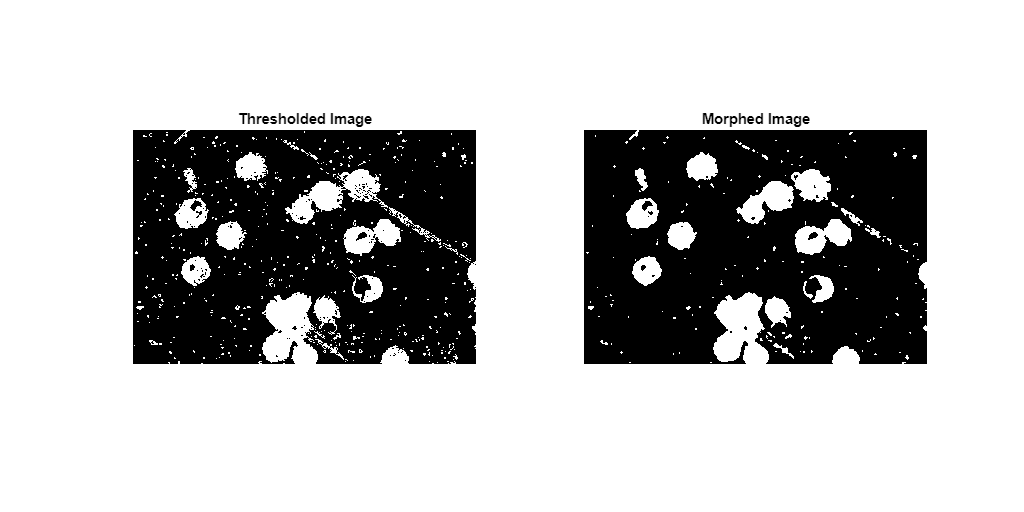

BW2 = bwmorph(BW,"majority");
figure('Position', [200, 200, 1024, 512]);
subplot(1,2,1); imshow(BW); title('Thresholded Image');
subplot(1,2,2); imshow(BW2); title('Morphed Image');

## Morphological opening

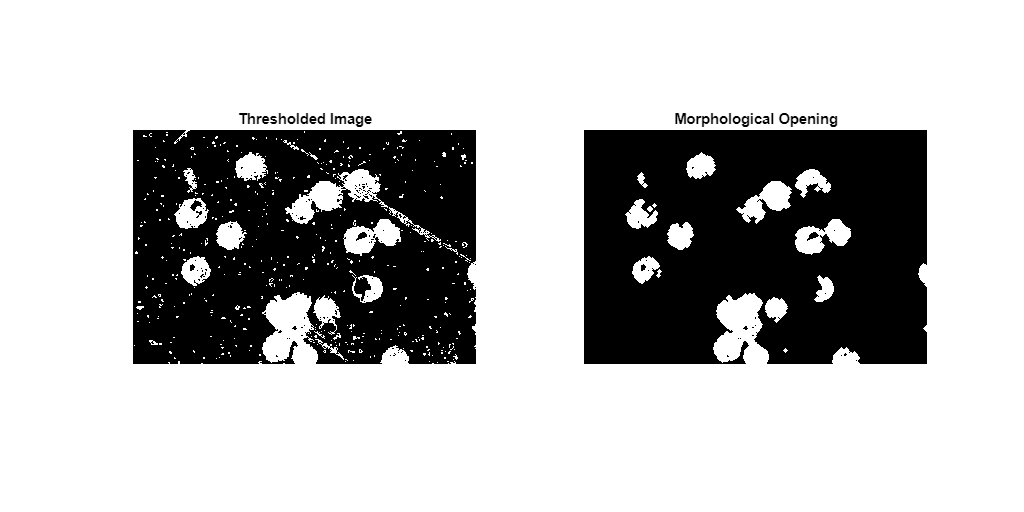

SE = strel("disk",2); 
BW3 = imopen(BW,SE);
figure('Position', [200, 200, 1024, 512]);
subplot(1,2,1); imshow(BW); title('Thresholded Image');
subplot(1,2,2); imshow(BW3); title('Morphological Opening');

## Morphological Closing

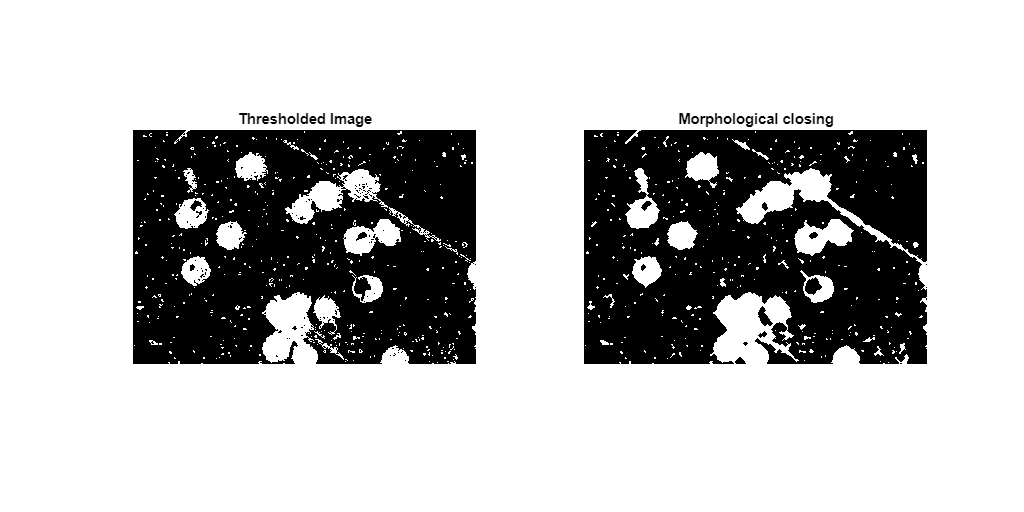

figure('Position', [200, 200, 1024, 512]);
BW4 = imclose(BW,SE);
subplot(1,2,1); imshow(BW); title('Thresholded Image');
subplot(1,2,2); imshow(BW4); title('Morphological closing');

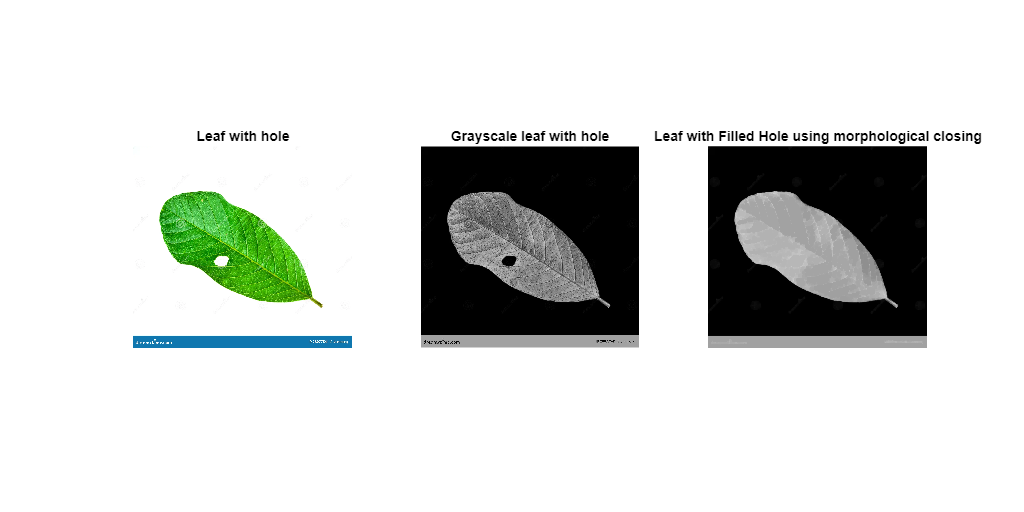

%% Application of Morphological Operations (Opening and Closing)
Image = imread('leaff.png');
I = rgb2gray(Image);
I = imcomplement(I);

%morphological closing to fill small holes
SE = strel('disk', 10); 
I_closed = imclose(I, SE);
I_clean = imfill(I_closed, 'holes');

%Plotting
figure('Position', [200, 200, 1024, 512]);
subplot(1, 3, 1); imshow(Image); title('Leaf with hole');
subplot(1, 3, 2); imshow(I); title('Grayscale leaf with hole');
subplot(1, 3, 3); imshow(I_clean); title('Leaf with Filled Hole using morphological closing');

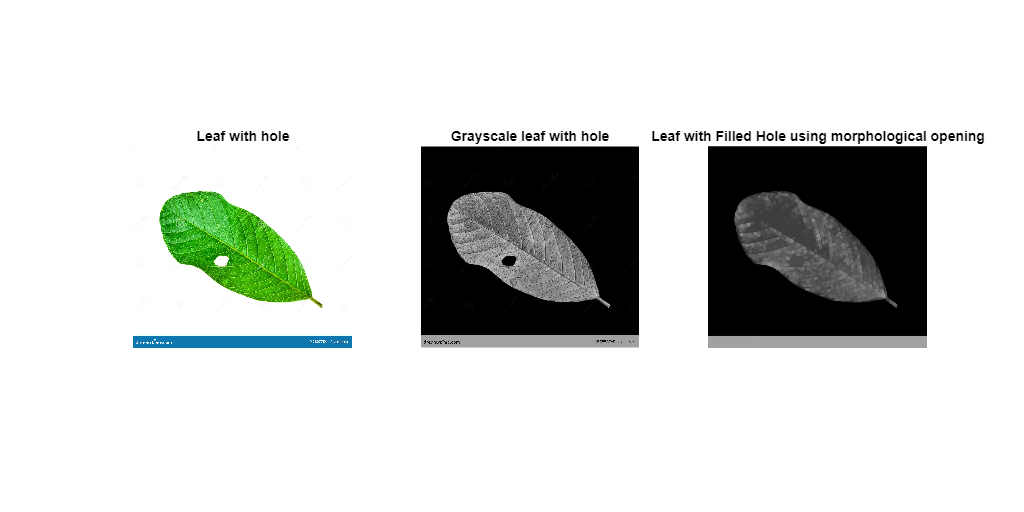

Image = imread('leaff.png');
I = rgb2gray(Image);
I = imcomplement(I);

%morphological opening to fill small holes
SE = strel('disk', 10); 
I_opened = imopen(I, SE);
I_clean = imfill(I_opened, 'holes');

%plotting
figure('Position', [200, 200, 1024, 512]);
subplot(1, 3, 1); imshow(Image); title('Leaf with hole');
subplot(1, 3, 2); imshow(I); title('Grayscale leaf with hole');
subplot(1, 3, 3); imshow(I_clean); title('Leaf with Filled Hole using morphological opening');

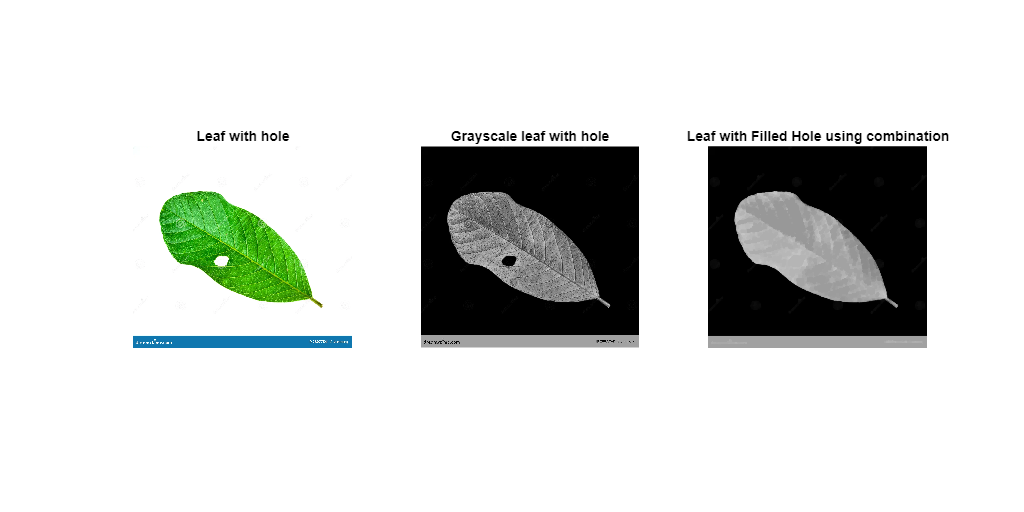

Image = imread('leaff.png');
I = rgb2gray(Image);
I = imcomplement(I);

%morphological closing to fill small holes
SE_close = strel('disk', 10); 
I_closed = imclose(I, SE_close);

% morphological opening to remove noise or small objects
SE_open = strel('disk', 5); 
I_clean = imopen(I_closed, SE_open);
I_clean = imfill(I_clean, 'holes');

%Plotting
figure;
figure('Position', [200, 200, 1024, 512]);
subplot(1, 3, 1); imshow(Image); title('Leaf with hole');
subplot(1, 3, 2); imshow(I); title('Grayscale leaf with hole');
subplot(1, 3, 3); imshow(I_clean); title('Leaf with Filled Hole using combination');

## References

%% https://www.mathworks.com/help/images/ref/strel.html
%% https://www.mathworks.com/help/images/ref/imdilate.html
%% https://www.mathworks.com/help/images/ref/imerode.html
%% https://www.mathworks.com/help/images/ref/imcomplement.html
%% https://www.mathworks.com/help/images/ref/imopen.html
%% https://www.mathworks.com/help/images/ref/imclose.html
%% https://www.mathworks.com/help/images/ref/imfill.html